**This code section works on a well-known problem of the 'birthday paradox', where the idea is to find at least 2 people that share a birthday in a sample of k people. **

The probability falls the more random samples are used, and the more people there are in each sample.

n=100 %  number of random samples tested

n = 100

probabilities=zeros(1,n) 

probabilities =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k=20 % number of people in 1 sample

k = 20

for i=1:n % repeat test n times
    birthday=randi([1,365],[1,k]);
    unbday=unique(birthday); % shows unique values of the previous vector, sorted
    numberOfUnique=numel(unbday); % shows number of elements in vector unbday
    log1(i)=numberOfUnique<k; % true for log(1) if x<50
    probabUpToNow=sum(log1(1:i)); 
    probabilities(i)=(probabUpToNow/i); 
    % prob=number of instances the event occurs/number of samples tested
end
probabilities

probabilities =     1.0000    1.0000    0.6667    0.7500    0.8000    0.6667    0.7143    0.7500    0.7778    0.7000    0.6364    0.5833    0.6154    0.5714    0.6000    0.6250    0.5882    0.6111    0.6316    0.6000    0.6190    0.5909    0.6087    0.5833    0.6000    0.6154    0.5926    0.6071    0.6207    0.6333    0.6129    0.5938    0.5758    0.5588    0.5429    0.5278    0.5135    0.5263    0.5128    0.5250    0.5122    0.5238    0.5349    0.5227    0.5333    0.5435    0.5532    0.5625    0.5510    0.5600


disp('Plotting the probability')

Plotting the probability


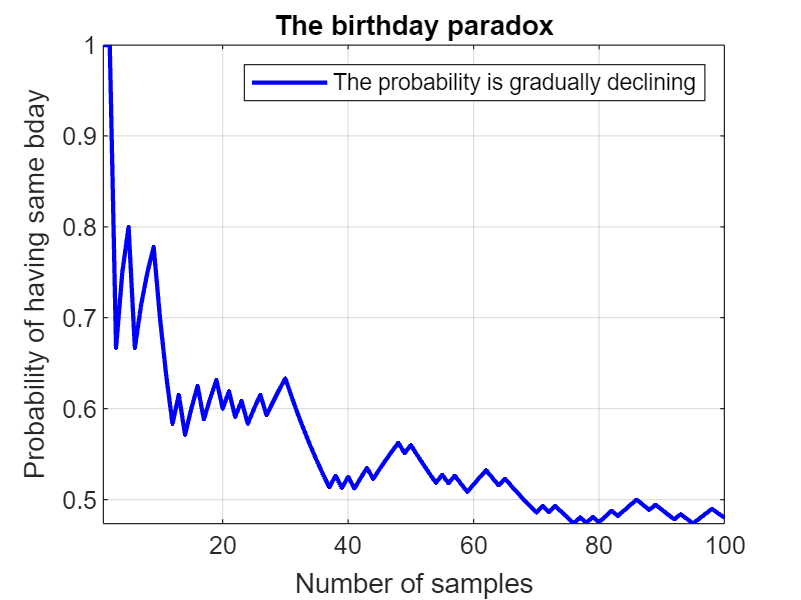

plot(1:n,probabilities,'b','linewidth',1.7)
grid on 
axis tight
xlabel('Number of samples')
ylabel('Probability of having same bday')
title('The birthday paradox')
legend("The probability is gradually declining")

**This and the following code sections perform elementary data analysis on Greenhouse gas emissions for some EU nations from 2000 to 2021. **

load emissions
emissions;
time=linspace(2000,2021,22)

time =         2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020        2021


emissions.Properties.VariableNames(1)={'Countries'}

emissions = 9×23 table
       Countries       VarName2    VarName3    VarName4    VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17    VarName18    VarName19    VarName20    VarName21    VarName22    VarName23
    _______________    ________    ________    ________    ________    ________    ________    ________    ________    ________

nations=emissions{:,1}

nations = 9×1 cell array
    {'Denmark'    }
    {'Germany'    }
    {'Ireland'    }
    {'Spain'      }
    {'France'     }
    {'Italy'      }
    {'Luxembourg' }
    {'Netherlands'}
    {'Portugal'   }


matrixemissions=emissions{:,2:end};
% each row is a separate nation
nandef1=matrixemissions(1,:); % denmark will have nans
nandef2=matrixemissions(2,:); % germany will have nans
nandef1(nandef1==106.9)=NaN;
nandef1(nandef1==100.6)=NaN

nandef1 =    99.2000       NaN  100.9000       NaN   99.5000   94.2000  104.1000   98.7000   92.4000   87.7000   86.8000   79.7000   73.5000   75.2000   71.1000   66.3000   70.4000   67.6000   69.9000   64.2000   58.5000   59.3000


nandef2(nandef2==82.7)=NaN;
nandef2(nandef2==70.9)=NaN;
disp('Modyfing data of emission matrix')

Modyfing data of emission matrix


matrixemissions(1:2,:)=[];
% deleting the first 2 rows of data
matrixemissions=[nandef1;nandef2;matrixemissions]

matrixemissions =    99.2000       NaN  100.9000       NaN   99.5000   94.2000  104.1000   98.7000   92.4000   87.7000   86.8000   79.7000   73.5000   75.2000   71.1000   66.3000   70.4000   67.6000   69.9000   64.2000   58.5000   59.3000
   81.6000   81.9000       NaN   82.1000   80.2000   78.2000   78.3000   76.5000   76.1000   70.3000   73.4000   71.0000       NaN   72.6000   70.0000   70.1000   70.2000   69.3000   66.9000   62.9000   57.6000   60.2000
  125.7000  131.4000  128.5000  130.0000  126.2000  130.3000  130.0000  126.7000  124.8000  113.7000  115.4000  107.0000  107.1000  108.4000  107.3000  112.4000  114.2000  117.8000  116.9000  113.4000  107.3000  112.8000
  135.2000  134.0000  141.5000  144.6000  150.8000  157.0000  153.7000  159.2000  146.2000  131.6000  125.0000  125.7000  123.7000  113.6000  113.7000  117.5000  113.4000  118.7000  116.5000  109.7000   90.7000   97.7000
  101.7000  100.2000   97.2000   97.1000   96.8000   97.1000   95.2000   93.9000   93.0000   90.60

**Greenhouse gas emissions: normalizing and smoothing data in order to uncover the trend:**

normalized=normalize(matrixemissions,2,'scale','first');
log3=isnan(normalized); % logical array with 1=NaN
ind=find(log3);
normalized(ind)=1

normalized =     1.0000    1.0000    1.0171    1.0000    1.0030    0.9496    1.0494    0.9950    0.9315    0.8841    0.8750    0.8034    0.7409    0.7581    0.7167    0.6683    0.7097    0.6815    0.7046    0.6472    0.5897    0.5978
    1.0000    1.0037    1.0000    1.0061    0.9828    0.9583    0.9596    0.9375    0.9326    0.8615    0.8995    0.8701    1.0000    0.8897    0.8578    0.8591    0.8603    0.8493    0.8199    0.7708    0.7059    0.7377
    1.0000    1.0453    1.0223    1.0342    1.0040    1.0366    1.0342    1.0080    0.9928    0.9045    0.9181    0.8512    0.8520    0.8624    0.8536    0.8942    0.9085    0.9372    0.9300    0.9021    0.8536    0.8974
    1.0000    0.9911    1.0466    1.0695    1.1154    1.1612    1.1368    1.1775    1.0814    0.9734    0.9246    0.9297    0.9149    0.8402    0.8410    0.8691    0.8388    0.8780    0.8617    0.8114    0.6709    0.7226
    1.0000    0.9853    0.9558    0.9548    0.9518    0.9548    0.9361    0.9233    0.9145    0.8909   

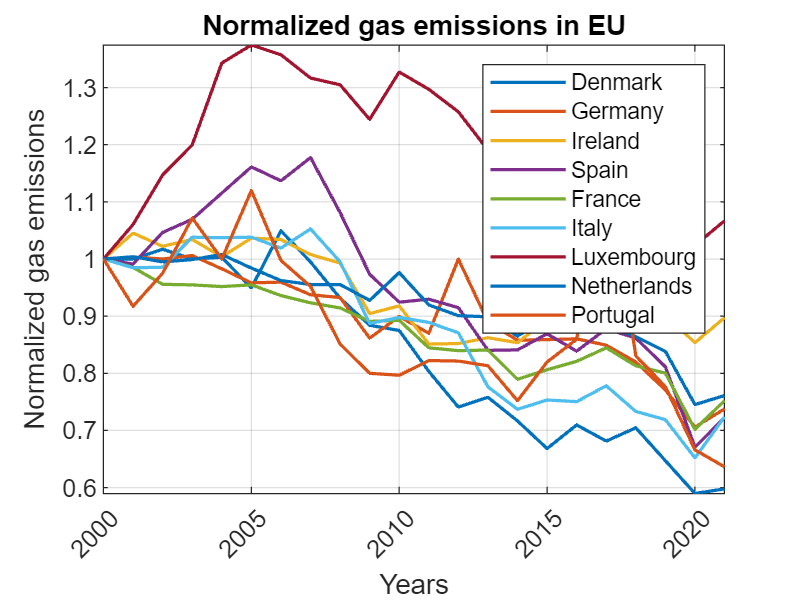

plot(time,normalized,'linewidth',1.3)
legend(nations)
axis tight
grid on
xlabel('Years')
xtickangle(45)
ylabel('Normalized gas emissions')
title('Normalized gas emissions in EU')

figure
datasm=smoothdata(normalized,"movmean",[2,2])

datasm =     1.0000    1.0163    1.0131    1.0134    0.9966    0.9815    1.0144    0.9801    0.9523    0.8834    0.8975    0.8416    0.8643    0.8367    0.8094    0.8072    0.8262    0.8226    0.8182    0.7734    0.7164    0.7443
    1.0000    1.0100    1.0215    1.0275    1.0263    1.0264    1.0450    1.0295    0.9846    0.9059    0.9043    0.8636    0.8770    0.8376    0.8173    0.8227    0.8293    0.8365    0.8290    0.7829    0.7050    0.7389
    1.0000    1.0051    1.0084    1.0129    1.0114    1.0121    1.0232    1.0082    0.9705    0.9029    0.9020    0.8598    0.8695    0.8382    0.8118    0.8194    0.8277    0.8381    0.8259    0.7864    0.7044    0.7415
    1.0000    1.0020    1.0021    1.0206    1.0183    1.0298    1.0172    1.0198    0.9833    0.9035    0.9065    0.8770    0.8955    0.8419    0.8158    0.8364    0.8358    0.8574    0.8316    0.8007    0.7169    0.7667
    1.0000    1.0134    1.0315    1.0593    1.0903    1.1131    1.0967    1.0956    1.0577    0.9801    0.9

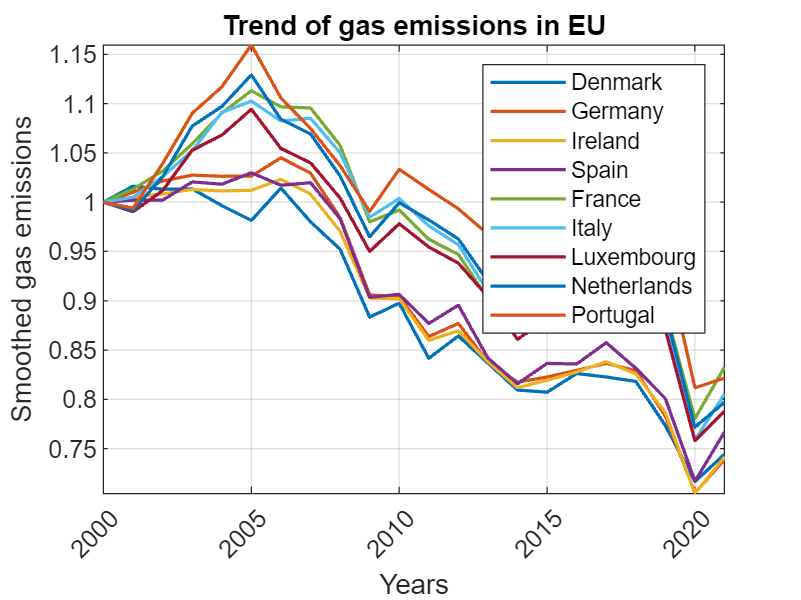

plot(time,datasm,'linewidth',1.3)
legend(nations)
axis tight
grid on
xlabel('Years')
xtickangle(45)
ylabel('Smoothed gas emissions')
title('Trend of gas emissions in EU')

% smoothed data shows a clear trend of decline

**An interactive drop down menu is created to visualize data for each country separately:**

disp('Creating a scatterplot')

Creating a scatterplot


matrixemissions

matrixemissions =    99.2000       NaN  100.9000       NaN   99.5000   94.2000  104.1000   98.7000   92.4000   87.7000   86.8000   79.7000   73.5000   75.2000   71.1000   66.3000   70.4000   67.6000   69.9000   64.2000   58.5000   59.3000
   81.6000   81.9000       NaN   82.1000   80.2000   78.2000   78.3000   76.5000   76.1000   70.3000   73.4000   71.0000       NaN   72.6000   70.0000   70.1000   70.2000   69.3000   66.9000   62.9000   57.6000   60.2000
  125.7000  131.4000  128.5000  130.0000  126.2000  130.3000  130.0000  126.7000  124.8000  113.7000  115.4000  107.0000  107.1000  108.4000  107.3000  112.4000  114.2000  117.8000  116.9000  113.4000  107.3000  112.8000
  135.2000  134.0000  141.5000  144.6000  150.8000  157.0000  153.7000  159.2000  146.2000  131.6000  125.0000  125.7000  123.7000  113.6000  113.7000  117.5000  113.4000  118.7000  116.5000  109.7000   90.7000   97.7000
  101.7000  100.2000   97.2000   97.1000   96.8000   97.1000   95.2000   93.9000   93.0000   90.60

nations

nations = 9×1 cell array
    {'Denmark'    }
    {'Germany'    }
    {'Ireland'    }
    {'Spain'      }
    {'France'     }
    {'Italy'      }
    {'Luxembourg' }
    {'Netherlands'}
    {'Portugal'   }


nation="Denmark"

nation = "Denmark"

log1=strcmp(nation,nations);
nationdata=matrixemissions(log1,:)

nationdata =    99.2000       NaN  100.9000       NaN   99.5000   94.2000  104.1000   98.7000   92.4000   87.7000   86.8000   79.7000   73.5000   75.2000   71.1000   66.3000   70.4000   67.6000   69.9000   64.2000   58.5000   59.3000


log2=isnan(nationdata)

log2 = 1×22 logical array
   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


nans=nnz(log2)

nans = 2

time=linspace(2000,2021,22)

time =         2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020        2021


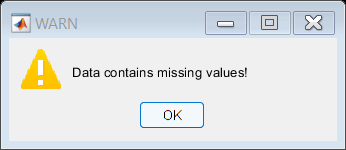

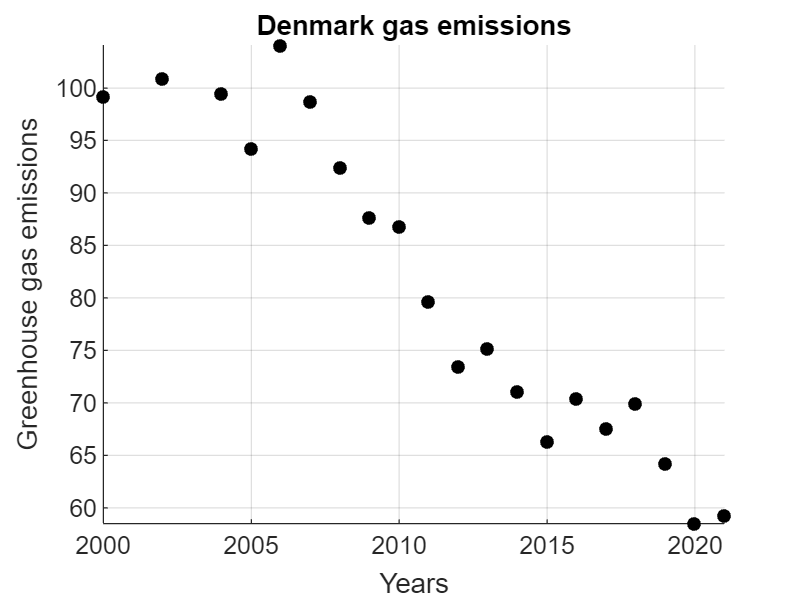

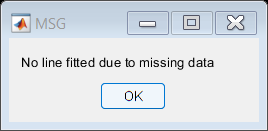

if nans>0
    warndlg("Data contains missing values!","WARN")
    scatter(time,nationdata,30,'k','filled')
    grid on
    axis tight
    xlabel('Years')
    ylabel('Greenhouse gas emissions')
    title(nation + ' gas emissions')
    msgbox("No line fitted due to missing data","MSG")
else
    scatter(time,nationdata,30,'k','filled')
    grid on
    axis tight
    xlabel('Years')
    ylabel('Greenhouse gas emissions')
    title(nation + ' gas emissions')
    hold on
    [polynom,~,scale]=polyfit(time,nationdata,1)
    fittedline=polyval(polynom,time,[],scale)
    plot(time,fittedline,'b','linewidth',1.3)
    legend("Scatter of data","Line of best fit")
    hold off
end 

**This code section provides the computation and visualization of the first n terms of the Fibonacci sequence: **

n=10 % number of elements in sequence

n = 10

fibo=zeros(1,n); % preallocation for speed
for i=2:n
    if i==2
        fibo(i)=1;
    else
        fibo(i)=fibo(i-1)+fibo(i-2);
    end
end 
disp(fibo'); % the sequence

     0
     1
     1
     2
     3
     5
     8
    13
    21
    34



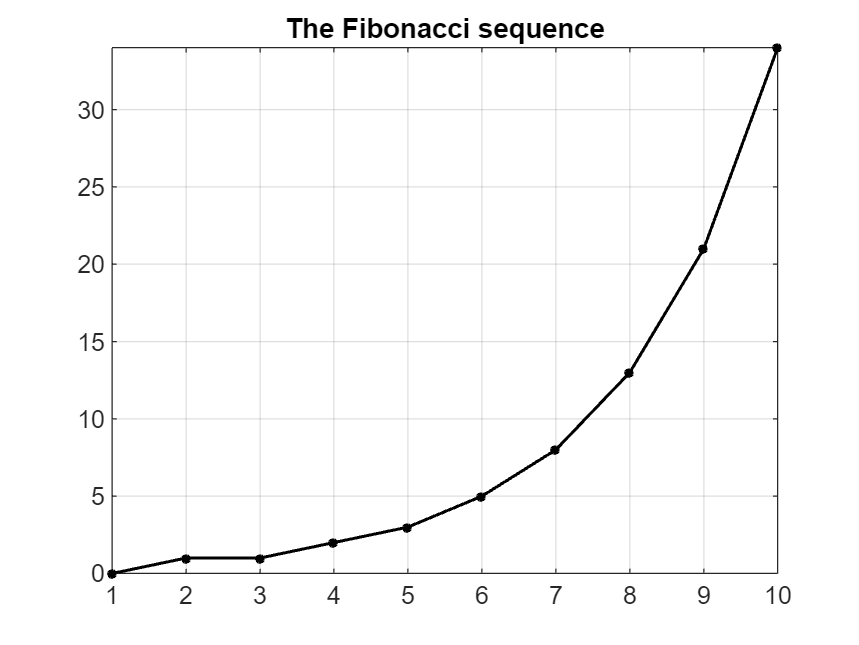

ans = 1452

d1 = datetime
   07-Sep-2023


d2 = calendarDuration
   7mo


d3 = datetime
   07-Apr-2024


d4 = calendarDuration
   15d


d5 = datetime
   22-Apr-2024


d6 = datetime
   22-Apr-2024


xaxis=linspace(1,n,n);
plot(xaxis,fibo,'k*-','MarkerSize',3.7,'linewidth',1.2)
grid on
axis tight
title('The Fibonacci sequence')